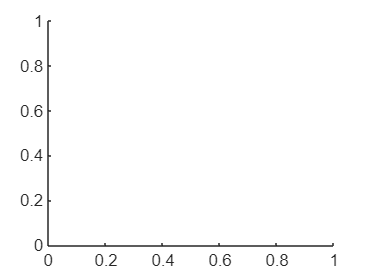

clc
clear all
load("matlab4.mat")
load("matlab5.mat")

T0 = 100000;
T = T0;
flag = 1;
SAiter = 1;
arrayRmse(1) = inf;
arrayRmse(2) = inf;
arrayRmse(3) = inf;
arrayRmse(4) = inf;
arrayRmse(5) = inf;
arrayRmse(6) = inf;
arrayRmse(7) = inf;
arrayRmse(8) = inf;
% while SAiter < 8 || flag
    a = 0.3;
    b = 0.1;
    c = 1;
    cnt = 1;
    K = 0.3;
    i = 0;
    pos1 = 1;
    pos2 = 1;
    temp = 0;
    index = 1;
    Length = 5;
    aaa = 0;
    ppp = 0;
    res = 0;
    TrainLimit = 6125;
    key = 0;
    limit1 = 0.5;
    limit2 = 0.03;
%     xseries = 1:4745;
%     xseries2 = 1:1378;
    u = 0;
    for j = 1:4
        res(j) = 0;
    end
    for j = 1:6125
        y(j) = PekingTemp(j);
    end
    YReal = 0;
%     for j = 4746:6123
%         YReal(j-4745) = PekingTemp(j);
%     end
    % while true
        deltaT = K * T;
        while index + Length < TrainLimit
            i = i + 1;
            for j = 1:Length
                dy(j) = abs(y(index) - Fourier_8(index));
                s2(j) = dy(j) * dy(j);
                temp = temp + s2(j);
                index = index + 1;
            end
            u(i) = temp;
            temp = 0;
            if i < 4 || u(i) > res(i)
                if i == 1
                    res(i+1) = u(i);
                    continue;
                end
                P = 5*exp(-abs(u(i)-u(i-1))/deltaT);
                P = P - 4.1;
                re_P(cnt) = P;
                cnt = cnt + 1;
                seed = rand(1);
                if seed > P || i < 4
                    forward1 = index - Length;
                    for j = 1:Length
                        forward1 = forward1 + 1;
                        fy(forward1) = y(forward1);
                        key = key + 1;
                    end
                    index = index - Length + 1;
                    if i > 4
                        tempx = length(u);
                        tempxx = 0;
                        for iii = 1 : tempx
                            tempxx(iii) = iii;
                        end
                        [tempx_ ,tempy_] = linear_predicion(tempxx,u);
                        num = tempy_;
                        res(i+1) = num(i+1);
                    else
                        res(i+1) = u(i);
                    end
                    continue;
                end
            end
            forward2 = index - Length + 1;
            for j = 1:Length
                ERR(j) = dy(j) / y(forward2);
                if ERR(j) > limit1
                    a = a * (1 + b * abs(tanh(ERR(j) - limit1)));
                elseif ERR(j) < limit2
                    a = a * (1 - b * abs(tanh(ERR(j) - limit2)));
                    if a < 0.01
                        a = 0.01;
                    end
                end
                if a < 10
                    aaa(pos2) = a;
                    pos2 = pos2 + 1;
                end
                gamma(j) = a * dy(j);
                if gamma(j) > dy(j)
                    gamma(j) = dy(j);
                end
                if y(forward2) > Fourier_8(forward2)
                    fy(forward2) = y(forward2) - gamma(j);
                else 
                    fy(forward2) = y(forward2) + gamma(j);
                end
                forward2= forward2 + 1;
            end
            tempx = length(u);
            tempxx = 0;
            for iii = 1 : tempx
                tempxx(iii) = iii;
            end
            [tempx_ ,tempy_] = linear_predicion(tempxx,u);
            num = tempy_;
            res(i+1) = num(i+1);
        end
%         if index < 4745
            for j = 4745 : -1 : index - Length
                fy(index) = y(index);
                index = index - 1;
            end
%         end
    %     plot(xseries,y,xseries,fy)
    indx = 1;
    temp = 0;
    for i = 1:13
        for j = 1:12
            index_month = (i-1)*12+j;
            for k = 1:30
                index_day = (i-1)*365+(j-1)*12+k;
                temp = temp + fy(index_day);
            end
            data(index_month) = temp/30;
            temp = 0;
        end
    end
    
    hold off

%     n_year=13; %length of data set
%     slen=12; %seasonal length
%     
%     b0=[];
%     for i=1:slen
%         b0=[b0 (data(i+slen)-data(i))/slen];
%     end
%     b0=sum(b0)/slen; % initial trend, here average of trend across seasons
%     
%     ap=[];
%     for j=1:n_year
%         ap=[ap sum(data(slen*(j-1)+1:slen*j))/slen];
%     end % averages of each year
%     
%     ym=zeros(slen,n_year);
%     for j=1:n_year
%         for i=1:slen
%             ym(i,j)=data(i+(j-1)*slen)/ap(j);
%         end
%     end % division by appropriate yearly mean
%     I=[];
%     for i=1:slen
%             I=[I sum(ym(i,:))/n_year];
%     end % initial seasonal components
%     
%     n_pred=12*4; %forecasting period
%     
%     
%     alpha=0.05;
%     beta=0.05;
%     gamma=0.05;
%     p=[alpha beta gamma]; %calibration parameters
%     X0=[p data n_pred b0 I slen]; %initial values
%         
%     options.Display='iter';
%     options.FunValCheck='on';
%     options.PlotFcns=@optimplotfval;
%     numbruns=200*length(p);
%     options.MaxFunEvals=numbruns;
%     options.MaxIter=numbruns;
%     
%     minFunc = @(p)holtwinters(p,data,n_pred,b0,I,slen);
%     [x,fval,exitflag,output]=fminsearch(minFunc,p,options)
%     
%     [ee,ts]=holtwinters(x,data,n_pred,b0,I,slen);
%     
%     % % visualisation of results
%     % figure(2)
%     % plot(data)
%     % hold on
%     % plot(ts,'--r')
%     temp = 0;
%     YPred = 0;
%     indx = 1;
%     each = 0;
%     for i = 1:4
%         for j = 1:12
%             iii = 156+(i-1)*12+j;
%             temp = temp + ts(iii);
%         end
%         YPred(indx) = temp/12;
%         indx = indx + 1;
%         temp = 0;
%     end
%     for i = 14:17
%         for j = 1:345
%             index = 4745+(i-14)*345+j;
%             each = each + PekingTemp(index);
%         end
%         each_year_latter_ave(i-13) = each / 345;
%         YReal(i-13) = each / 345;
%         each = 0;
%     end
%     YReal = 0;
%     mae = mean(abs(YReal - YPred))
%     sse = sum((YPred - YReal).^2)
%     rmse = sqrt(mean((YPred-YReal).^2))
%     meap = mean(abs((YReal - YPred)./YReal))*100 
%     SAiter = SAiter + 1;
%     arrayRmse(SAiter) = rmse; 
%     T = T - K*T
%     if SAiter > 8
%         flag = 0;
% %         for iii = 1:3
% %              if arrayRmse(SAiter-iii+1) > arrayRmse(SAiter-iii)
% %                  break
% %              end
% %              if iii == 3
% %                  flag = 0;
% %              end
% %         end
%     end
% end
SAiter

SAiter = 1

YReal = 0;
YPred = 0;
% fy(4745) = fy(4744);
for i = 1:4745
    yyyy(i) = fy(i);
end
for i = 4746:6125
    yyyy(i) = PekingTemp(i);
end
for i = 4746:6123
    YReal(i-4745) = PekingTemp(i);
end



%序列的前 77.5% 用于训练，后 22.5% 用于测试
Y1 = yyyy;
data = Y1;
numTimeStepsTrain = floor(0.775*numel(data));
dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);
 
%数据预处理，将训练数据标准化为具有零均值和单位方差。
mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;
 
%输入LSTM的时间序列交替一个时间步
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

%%
%创建LSTM回归网络，指定LSTM层的隐含单元个数96*3
%序列预测，因此，输入一维，输出一维
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 96*3;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
 
%指定训练选项，求解器设置为adam， 250 轮训练。
%梯度阈值设置为 1。指定初始学习率 0.005，在 125 轮训练后通过乘以因子 0.2 来降低学习率。
options = trainingOptions('adam', ...
    'MaxEpochs',300, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');
%训练LSTM
net = trainNetwork(XTrain,YTrain,layers,options);

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
YTest = dataTest(2:end);

net = resetState(net);
net = predictAndUpdateState(net,XTrain);
 
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
 
%使用先前计算的参数对预测去标准化。
YPred = sig*YPred + mu;
 
%计算均方根误差 (RMSE)。
rmse = sqrt(mean((YPred-YTest).^2))

%将预测值与测试数据进行比较。
figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Loads")
title("Forecast with Updates")
 
subplot(2,1,2)
stem(YPred - YTest)
xlabel("Days")
ylabel("Error")
title("RMSE = " + rmse)
 
 
figure
subplot(2,1,1)
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Days")
ylabel("Loads")
title("Forecast")
legend(["Observed" "Forecast"])
subplot(2,1,2)
plot(data)
xlabel("Days")
ylabel("Loads")
title("Daily load")

mae = mean(abs(YReal - YPred))
sse = sum((YPred - YReal).^2)
rmse = sqrt(mean((YPred-YReal).^2))
meap = mean(abs((YReal - YPred)./YReal))*100

YPredForSAGM = YPred;
YPredForSAGM(1379) = YPredForSAGM(1378);
YPredForSAGM(1380) = YPredForSAGM(1378);
